%Implementação de um filtro butterworth de terceira ordem utilizando um
%filtro de primeira ordem e um filtro sallen key de segunda ordem
%Andrea Mara Weber e Luana Bremm


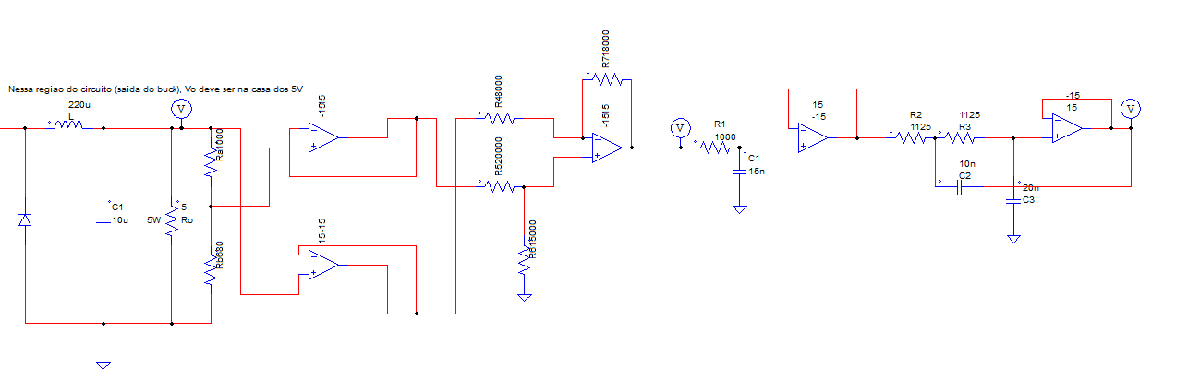

%Vx -> saída do divisor
Vx = 5*(680/(1000+680))

Vx = 2.0238

Vx

Vx = 2.0238

%buffers e circuito subtrator
Vout = (18000/8000)*(Vx-5)

Vout = -6.6964

Vout

Vout = -6.6964

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



%optamos por utilizar um filtro butterworth, tendo fator de qualidade
%Q=0,707 e ganho kc=1
%tendo escolhido o valor do capacitor c2 fixo como 10nF, teremos:


%filtro de primeira ordem
fc = 10000

fc = 10000

R1 = 1000

R1 = 1000

C1 = 1/(2*pi*fc*R1)

C1 = 1.5915e-08

C1

C1 = 1.5915e-08


%filtro de segunda ordem sallen key
Q = 0.707%fator de qualidade escolhido

Q = 0.7070

C2 = 10*(10^(-9))

C2 = 1.0000e-08


C3 = ((Q/(0.5))^2)*C2

C3 = 1.9994e-08


%comparação entre os sinais de entrada e saída